Opgaver

Opgave 13.27

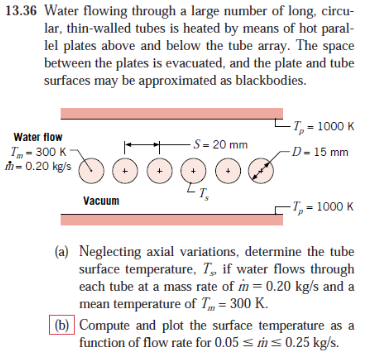

clear all
clf
format short g
CoolProp = py.importlib.import_module('CoolProp.CoolProp');
P_atm = 101325; % Pascal eller 1e5
fluid = 'water'

fluid = 'water'


T_m = 300; % K % Temperature in pipes
T_p = 1000; %K % plate temperature
m_dot = 0.20; %kg/s masse flow af vand i rørende
S = 0.020; % m % afstand fra center til center af rør
D = 0.015; % m % Diameter af rør
epsilon = 1; % emissiviteten af en black body

k = CoolProp.PropsSI('conductivity', 'P', P_atm, 'T', T_m, fluid)

k =        0.6095


c_p = CoolProp.PropsSI('Cpmass', 'P', P_atm, 'T', T_m, fluid) %specificHeat_p

c_p =        4180.6


mu = CoolProp.PropsSI('viscosity', 'P', P_atm, 'T', T_m, fluid) %Dynamisk viscositet

mu =    0.00085374


rho = CoolProp.PropsSI('D', 'P', P_atm, 'T', T_m, fluid) %Densitet

rho =        996.56


Pr = CoolProp.PropsSI('Prandtl', 'P', P_atm, 'T', T_m, fluid)

Pr =        5.8559


% eta = nu * rho;
nu = mu / rho

nu =    8.5669e-07


sigma = 5.670374419e-8; % J/K %stefan-boltzman konstant


syms T_s L h_sym
% L = 1;
A_pipe = 6 /2 * 2 * pi * (D/2) * L 

$$A\_pipe = \frac{9\,\pi \,L}{200}$$

b_plade = 6*S

b_plade =          0.12


A_plade = b_plade * L

$$A\_plade = \frac{3\,L}{25}$$

Det antages 

- steady state

- ingen konductions modstand i gennem rørende

- ingen varme generation

- ingen axial bidrag

- all are black bodies

- antager at plader og rør er ens


$$\dot{E}_{ind} - \dot{E}_{ud} = 0$$
 


$$q_{conv} = q_{rad}$$


Til at finde strålingen bruger vi tabel 13.1

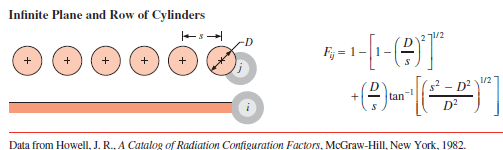

F_ij = 1 - sqrt(1 - (D/S)^2) + (D/S) * atan(sqrt((S^2 -D^2) / D^2))

F_ij =       0.88061


q_rad = epsilon * sigma * A_plade * F_ij * (T_p^4 - T_s^4);

Til at finde convectionen i røret bruger vi

tabel 8.4 giver overblik over nussel tal og vi kan her finde det der passer til ens senarie

L_c = D; % den karakteristiske længde
n = 0.4; % T_s > T_m
Re_D = 4 * m_dot / (pi * D * mu)

Re_D =         19885


Nu_D = 0.023 * Re_D^(4/5) * Pr^n

Nu_D =        128.11


h = double(solve(Nu_D == h_sym * L_c / k))

h =        5205.5


q_conv = A_pipe * h * (T_s - T_m);

T_s_sol = double(solve(q_conv == q_rad, T_s));
T_s_final = T_s_sol(1)

T_s_final =        308.07



q_rad_end = subs(q_rad, T_s, T_s_final);
q_conv_end = subs(q_conv, T_s, T_s_final);

**b)**

m_dots = 0.05:0.01:0.25;
for i = 1:length(m_dots)
    m_dot = m_dots(i)
    Re_D = 4 * m_dot / (pi * D * mu)
    Nu_D = 0.023 * Re_D^(4/5) * Pr^n
    h = double(solve(Nu_D == h_sym * L_c / k))
    q_conv = A_pipe * h * (T_s - T_m);

    T_s_sol = double(solve(q_conv == q_rad, T_s));
    T_s_final = T_s_sol(1)
    T_s_finals(i) = T_s_final 

    q_rad_end = subs(q_rad, T_s, T_s_final);
    q_conv_end = subs(q_conv, T_s, T_s_final);
end

m_dot =          0.05


Re_D =        4971.2


Nu_D =        42.261


h =        1717.2


T_s_final =        324.41


T_s_finals =        324.41


m_dot =          0.06


Re_D =        5965.5


Nu_D =        48.897


h =        1986.8


T_s_final =        321.11


T_s_finals =        324.41       321.11


m_dot =          0.07


Re_D =        6959.7


Nu_D =        55.314


h =        2247.6


T_s_final =        318.66


T_s_finals =        324.41       321.11       318.66


m_dot =          0.08


Re_D =        7953.9


Nu_D =        61.551


h =          2501


T_s_final =        316.78


T_s_finals =        324.41       321.11       318.66       316.78


m_dot =          0.09


Re_D =        8948.2


Nu_D =        67.632


h =        2748.1


T_s_final =        315.27


T_s_finals =        324.41       321.11       318.66       316.78       315.27


m_dot =           0.1


Re_D =        9942.4


Nu_D =         73.58


h =        2989.8


T_s_final =        314.04


T_s_finals =        324.41       321.11       318.66       316.78       315.27       314.04


m_dot =          0.11


Re_D =         10937


Nu_D =         79.41


h =        3226.7


T_s_final =        313.01


T_s_finals =        324.41       321.11       318.66       316.78       315.27       314.04       313.01


m_dot =          0.12


Re_D =         11931


Nu_D =        85.134


h =        3459.3


T_s_final =        312.14


T_s_finals =        324.41       321.11       318.66       316.78       315.27       314.04       313.01       312.14


m_dot =          0.13


Re_D =         12925


Nu_D =        90.764


h =          3688


T_s_final =        311.38


T_s_finals =        324.41       321.11       318.66       316.78       315.27       314.04       313.01       312.14       311.38


m_dot =          0.14


Re_D =         13919


Nu_D =        96.308


h =        3913.3


T_s_final =        310.73


T_s_finals =        324.41       321.11       318.66       316.78       315.27       314.04       313.01       312.14       311.38       310.73


m_dot =          0.15


Re_D =         14914


Nu_D =        101.77


h =        4135.4


T_s_final =        310.15


T_s_finals =        324.41       321.11       318.66       316.78       315.27       314.04       313.01       312.14       311.38       310.73       310.15


m_dot =          0.16


Re_D =         15908


Nu_D =        107.17


h =        4354.5


T_s_final =        309.64


T_s_finals =        324.41       321.11       318.66       316.78       315.27       314.04       313.01       312.14       311.38       310.73       310.15       309.64


m_dot =          0.17


Re_D =         16902


Nu_D =        112.49


h =        4570.9


T_s_final =        309.19


T_s_finals =        324.41       321.11       318.66       316.78       315.27       314.04       313.01       312.14       311.38       310.73       310.15       309.64       309.19


m_dot =          0.18


Re_D =         17896


Nu_D =        117.75


h =        4784.8


T_s_final =        308.78


T_s_finals =        324.41       321.11       318.66       316.78       315.27       314.04       313.01       312.14       311.38       310.73       310.15       309.64       309.19       308.78


m_dot =          0.19


Re_D =         18891


Nu_D =        122.96


h =        4996.3


T_s_final =        308.41


T_s_finals =        324.41       321.11       318.66       316.78       315.27       314.04       313.01       312.14       311.38       310.73       310.15       309.64       309.19       308.78       308.41


m_dot =           0.2


Re_D =         19885


Nu_D =        128.11


h =        5205.5


T_s_final =        308.07


T_s_finals =        324.41       321.11       318.66       316.78       315.27       314.04       313.01       312.14       311.38       310.73       310.15       309.64       309.19       308.78       308.41       308.07


m_dot =          0.21


Re_D =         20879


Nu_D =        133.21


h =        5412.7


T_s_final =        307.76


T_s_finals =        324.41       321.11       318.66       316.78       315.27       314.04       313.01       312.14       311.38       310.73       310.15       309.64       309.19       308.78       308.41       308.07       307.76


m_dot =          0.22


Re_D =         21873


Nu_D =        138.26


h =          5618


T_s_final =        307.48


T_s_finals =        324.41       321.11       318.66       316.78       315.27       314.04       313.01       312.14       311.38       310.73       310.15       309.64       309.19       308.78       308.41       308.07       307.76       307.48


m_dot =          0.23


Re_D =         22868


Nu_D =        143.27


h =        5821.4


T_s_final =        307.22


T_s_finals =        324.41       321.11       318.66       316.78       315.27       314.04       313.01       312.14       311.38       310.73       310.15       309.64       309.19       308.78       308.41       308.07       307.76       307.48       307.22


m_dot =          0.24


Re_D =         23862


Nu_D =        148.23


h =          6023


T_s_final =        306.97


T_s_finals =        324.41       321.11       318.66       316.78       315.27       314.04       313.01       312.14       311.38       310.73       310.15       309.64       309.19       308.78       308.41       308.07       307.76       307.48       307.22       306.97


m_dot =          0.25


Re_D =         24856


Nu_D =        153.15


h =        6222.9


T_s_final =        306.75


T_s_finals =        324.41       321.11       318.66       316.78       315.27       314.04       313.01       312.14       311.38       310.73       310.15       309.64       309.19       308.78       308.41       308.07       307.76       307.48       307.22       306.97       306.75


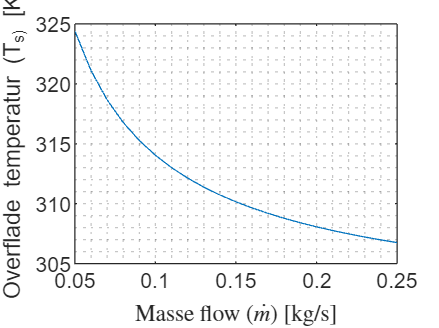


figure
plot(m_dots, T_s_finals)%, DisplayName='h=15 [W/m^2]')
ylabel('Overflade temperatur (T_s) [K]')
xlabel('Masse flow $\left(\dot{m}\right)$ [kg/s]', Interpreter='latex')
grid("minor")

% legend('Location','best')


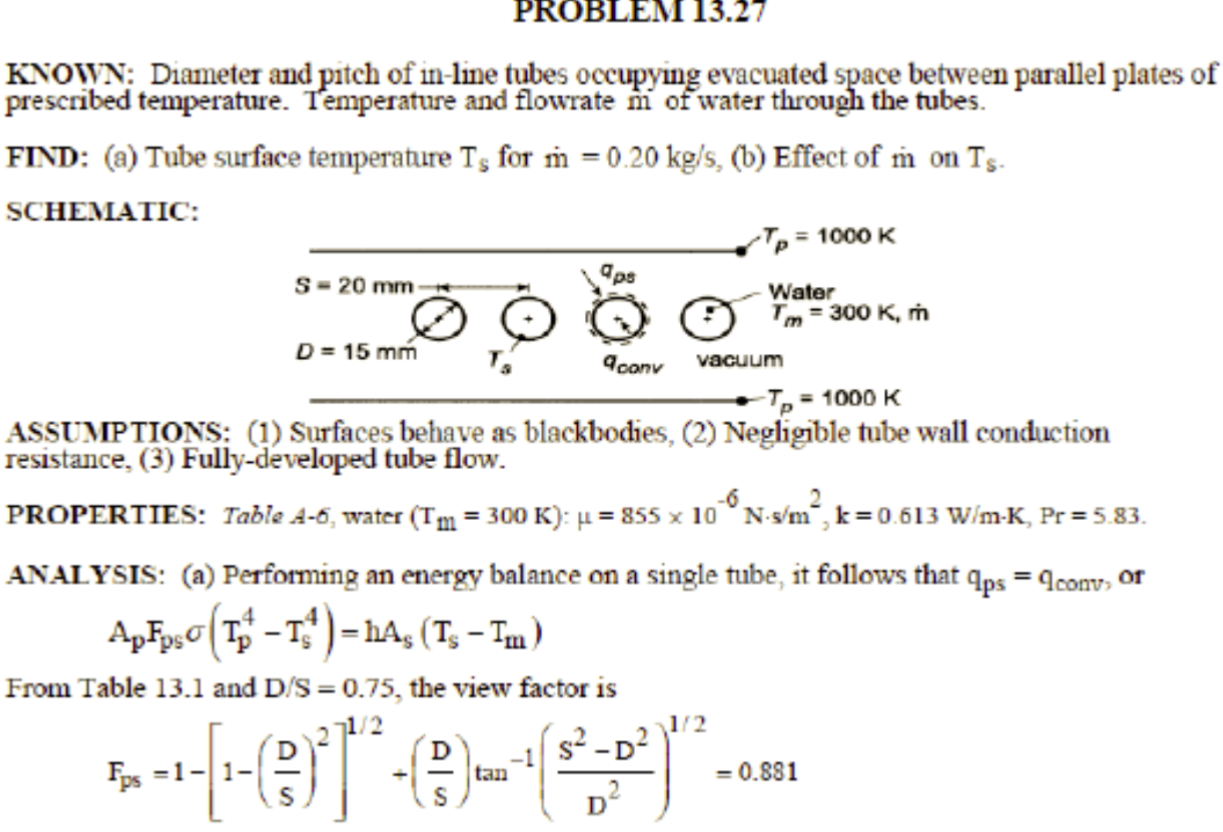

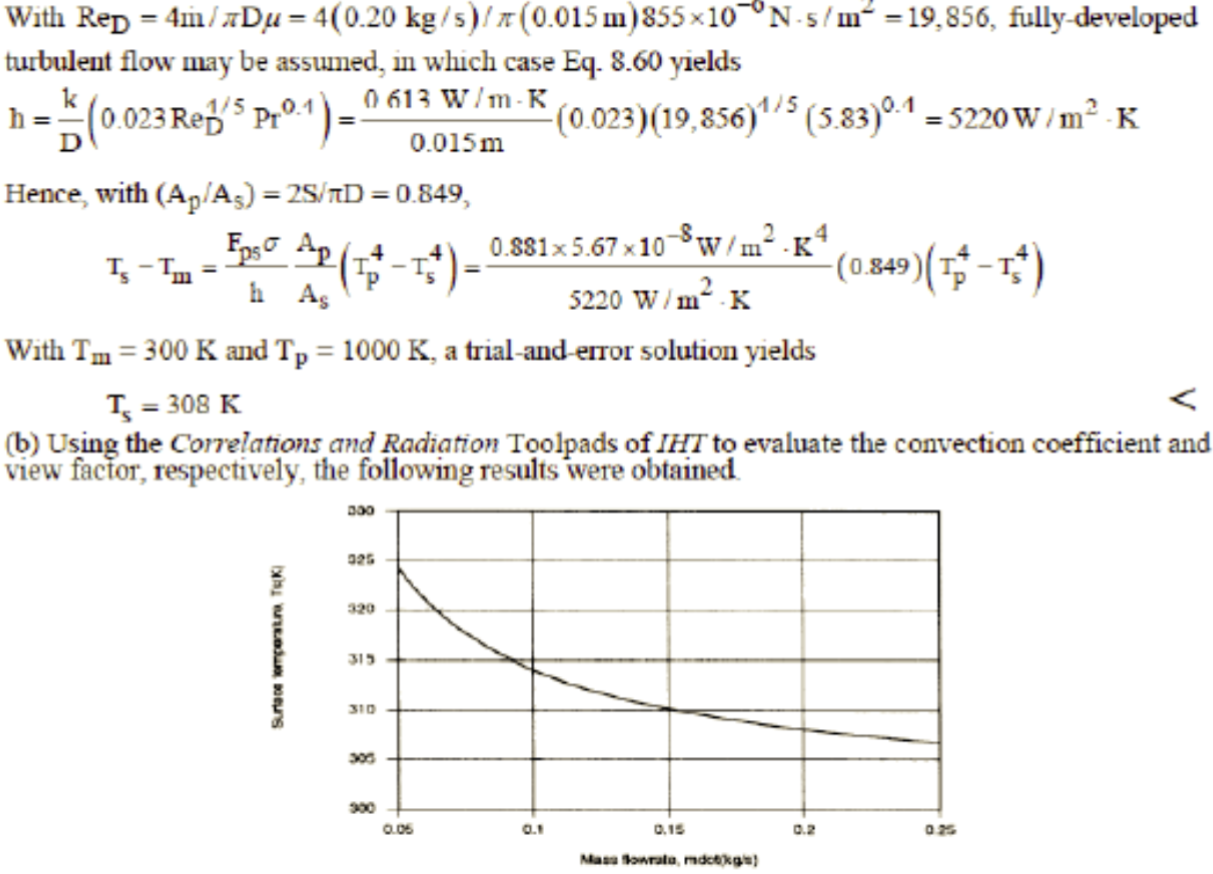

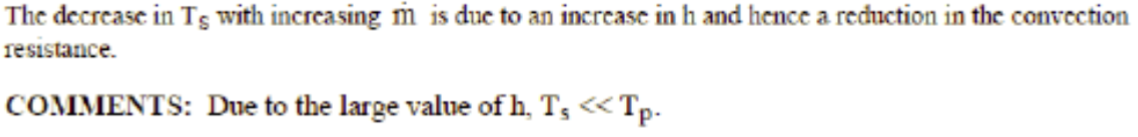

Opgave 13.74

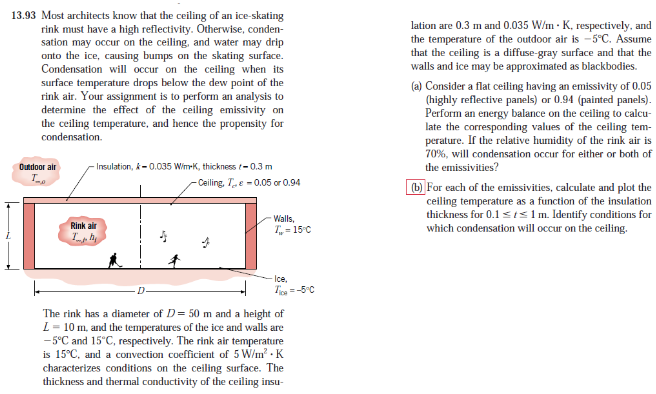

clear all
clf
format short g
CoolProp = py.importlib.import_module('CoolProp.CoolProp');
% CoolPropHu = py.importlib.import_module('CoolProp.HumidAirProp');

P_atm = 101325; % Pascal eller 1e5
fluid = 'air';
K = 273.15; 
sigma = 5.670374419e-8; % J/K %stefan-boltzman konstant

L = 10; % m %loft til gulv
k_iso = 0.035; % W/(m*K) % carme konductivitet af isoleringen
t_c = 0.3; % tykkelse af loftets isolering
epsilon = 0.94 % or 0.94 or 0.05

epsilon =          0.94


syms T_loft
T_w = 15 + K; % K % væg temperatur
T_luft = T_w; %K % luft temperaturen
T_ice = -5 + K; % K % is temperatur
T_out = -5 + K; % K % udendørs temperatur
D = 50; % m diameter af hallen
T_air = 15 + K; % luft temperaturen
h = 5; % W/(m^2 * K)
A_loft = pi * (D/2)^2

A_loft =        1963.5


A_gulv = A_loft

A_gulv =        1963.5


A_wall = pi*D * L

A_wall =        1570.8


T_dug = 9.6 + K; % K % dugpunkt temperaturen
% T_dew_K = CoolPropHu.HAPropsSI('DewPoint','T',T_luft,'P',P_atm,'R',0.7)
% T_dew_C = T_dew_K - K

Det antages 

- steady state

- Vægge og gulv er black body

- ingen varme generation

- ingen varme konduction igennem væg og gulv

- yder vægs temperaturen er en med luft temperaturen

- ingen stråling ud af taget


$$\dot{E}_{ind} - \dot{E}_{ud} = 0$$
 


$$q_{conv} + q_{rad,v\ae g} - q_{rad,gulv}  = q_{cond,loft}$$


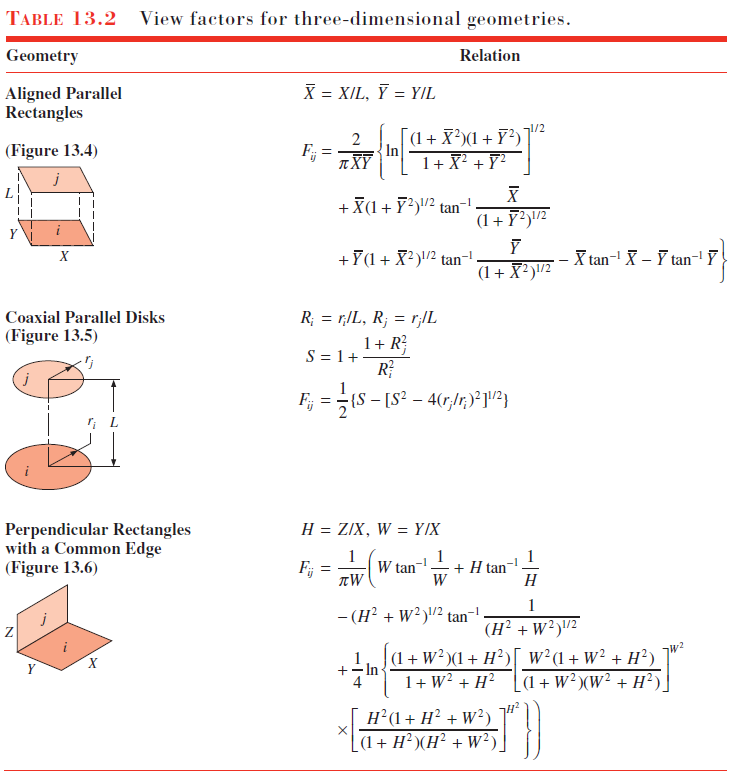

% R_cond = t_c/(A_loft * k_iso)
q_cond_loft = A_loft*k_iso*(T_loft - T_out) / t_c

$$q\_cond\_loft = \frac{875\,\pi \,\left(T_{\mathrm{loft}}-\frac{5363}{20}\right)}{12}$$

% q_cond_loft = (T_loft - T_out)/ R_cond
vpa(q_cond_loft, 6)

$$ans = 229.074\,T_{\mathrm{loft}}-61426.3$$

q_conv = A_wall * h * (T_loft-T_luft)

$$q\_conv = 2500\,\pi \,\left(T_{\mathrm{loft}}-\frac{5763}{20}\right)$$

vpa(q_conv, 6)

$$ans = 7853.98\,T_{\mathrm{loft}}-2263120.0$$


alpha = epsilon; % grey body enclosed
ri = D/2;
rj = ri;
Ri = ri / L

Ri =           2.5


Rj = rj/L

Rj =           2.5


S = 1 + ((1 + Rj^2) /Ri^2)

S =          2.16


F_ic = 1/2 * (S - sqrt(S^2 - 4*(ri/rj)^2)) % i = gulv, j = loft

F_ic =       0.67208



% F_ic + F_iw = 1 % symatri
F_cw = 1 - F_ic % summations reglen

F_cw =       0.32792


F_wc = (A_loft / A_wall) * F_cw % reciprok reglen

F_wc =        0.4099



E_rad_loft = epsilon * sigma * A_loft * T_loft^4

$$E\_rad\_loft = \frac{3861172446826963\,{T_{\mathrm{loft}}}^{4}}{36893488147419103232}$$

vpa(E_rad_loft,5)

$$ans = 0.00010466\,{T_{\mathrm{loft}}}^{4}$$

G_rad_ice = alpha * sigma * A_gulv * F_ic * T_ice^4

G_rad_ice =    3.6366e+05


G_rad_wall = alpha * sigma * A_wall * F_wc * T_w^4

G_rad_wall =     2.366e+05



q_rad = E_rad_loft - G_rad_ice - G_rad_wall

$$q\_rad = \frac{3861172446826963\,{T_{\mathrm{loft}}}^{4}}{36893488147419103232}-\frac{20624908873327493}{34359738368}$$

T_eq = double(solve( 0 == q_cond_loft +q_conv + q_rad, T_loft)) 

T_eq =        281.05 +          0i
       114.12 -     426.86i
       114.12 +     426.86i
       -509.3 +          0i


T_loft_sol = T_eq(1) - K 

T_loft_sol =         7.905


% 13.9

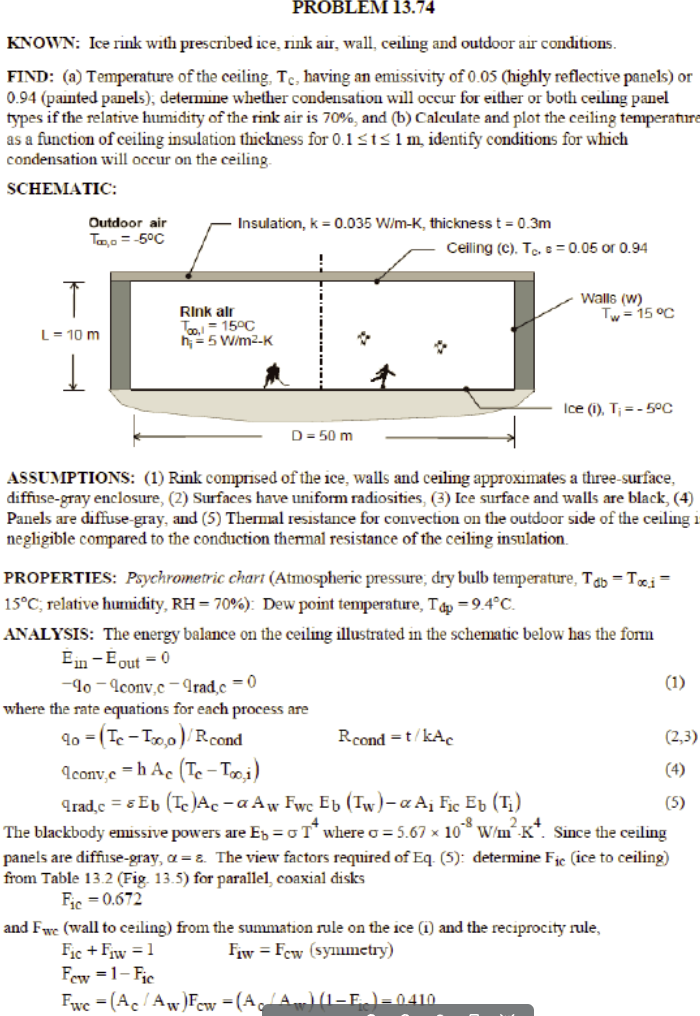

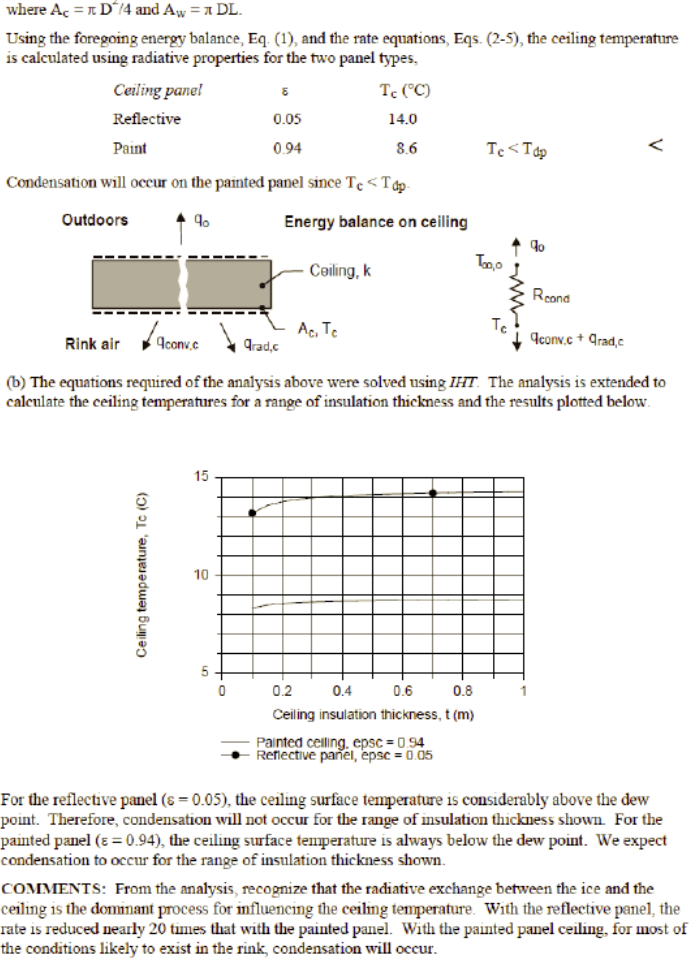

Eksamepler

eksempel 13.3

eksempel 13.4

eksempel 13.6

Figurer og tabeller

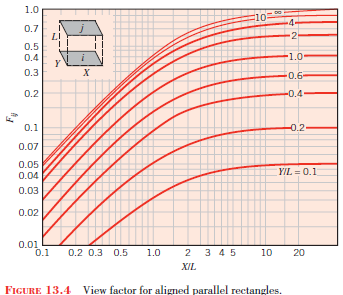

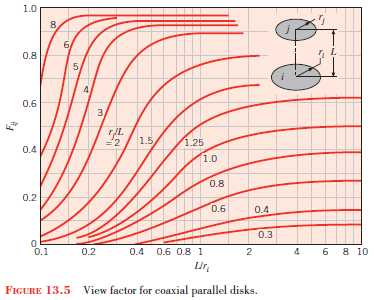

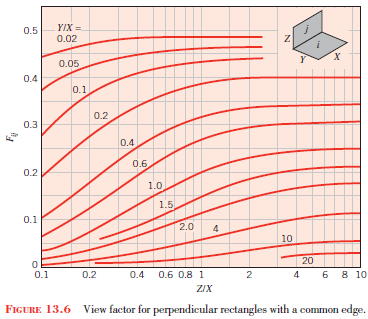

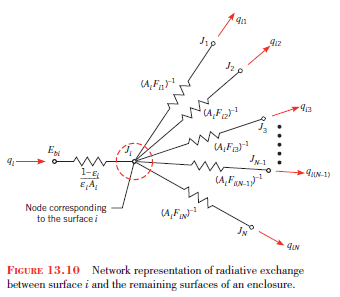

Forstå sammenhængene mellem figur 13.11, formel 13.23 og tabel 13.3.